# On the linearity of spectral power estimates of multiple signals

Sebastien Proulx (email: jsproulx@mgh/harvard.edu; orcid: 0000-0003-1709-3277)

2023-08-15

clear all
close all
%% Dependency
% Colored noise generation by Miroslav Stoyanov, Oak Ridge National
% Laboratory
% (https://people.sc.fsu.edu/~jburkardt/m_src/cnoise/cnoise.html)
websave('f_alpha_gaussian.m','https://people.sc.fsu.edu/~jburkardt/m_src/cnoise/f_alpha_gaussian.m');

## Summation of periodic signals

The fourrier transform is a linear operation, meaning that ["the Fourier Transform of a sum of functions is the sum of the Fourier Transforms of the [same] functions"](https://lpsa.swarthmore.edu/Fourier/Xforms/FXProps.html). Summing two periodic signals in time-domain (e.g. summing two sinusoidals before computing the fft) is therefore equivalent to summing the same signals in frequency-domain (e.g. computing the fft of two signals then summing the results). This is shown in the simulation below using parameters close to our fast single-slice fMRI experiments and comparing the time-domain sum (black trace) to the frequency-domain sum (red trace) of two signals.

Linearity however does not hold for power spectral density (psd)--the green trace below shows that summing psd is not equivalent to the psd of the summed signal. This is likely due to the psd operation turning complex values to real values.

%% Simulation parameters
n = 4096;
t = ((1:n)-1).*0.081; % simulate fMRI timeseries with TR=0.081s
f = 0:((1/0.081)/(n-1)):(1/0.081)/2;

%% Sinusoidal signals
sig1Freq = 0.1;
sig1Amp = 5;
sig1Ts = sig1Amp.*sin(2*pi*sig1Freq*t)';
sig2Freq = 0.16;
sig2Amp = 5;
sig2Ts = sig2Amp.*sin(2*pi*sig2Freq*t)';

%% Fourier transform
sig1Spec = fft(sig1Ts); sig1Spec = sig1Spec(1:n/2,:);
sig2Spec = fft(sig2Ts); sig2Spec = sig2Spec(1:n/2,:);
sig1n2Spec = fft(sig1Ts+sig2Ts); sig1n2Spec = sig1n2Spec(1:n/2,:);
sig1Psd = (1/(1/0.081*n)) * abs(sig1Spec).^2; 
sig2Psd = (1/(1/0.081*n)) * abs(sig2Spec).^2; 
sig1n2Psd = (1/(1/0.081*n)) * abs(sig1n2Spec).^2; 

%% Plot
figure
hPlot1 = plot(f,sig1Psd);

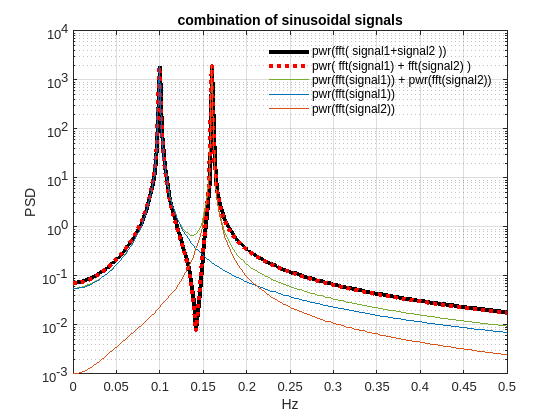

hold on
hPlot2 = plot(f,sig2Psd);
plot(f,sig1n2Psd,'-k','LineWidth',3);
plot(f, (1/(1/0.081*n)) * abs(sig1Spec+sig2Spec).^2 ,'r:','LineWidth',3);
plot(f,sig1Psd+sig2Psd);
grid on

%% Adjust plot
ax = gca;
ax.XLim = [f(1) 0.5];
ax.YScale = 'log';
xlabel('Hz'); ylabel('PSD');
legend({
    'pwr(fft(signal1))'
    'pwr(fft(signal2))'
    'pwr(fft( signal1+signal2 ))'
    'pwr( fft(signal1) + fft(signal2) )'
    'pwr(fft(signal1)) + pwr(fft(signal2))'
    },'location','northeast','box','off')
uistack([hPlot2 hPlot1],'top')
drawnow
title('combination of sinusoidal signals')

## Signal and noise combination in time- and frequency-domain

Periodic signals in noisy timeseries are often studied in the frequency-domain using psd. From the linearity of the fourrier transform that underlies psd computation, one may intuite that a periodic signal can be quantified in frequency domain from the difference between psd at the peak and psd of the noise baseline. Under this logic, as noise level rises, the peak of a periodic signal will be "lifted" by the noise baseline. This is howver not the case, as is demonstrated below for a fixed sinusoidal signal combined in time-domain with varying levels of white noise. It can be observed that as the noise baseline rises up, the signal peak is not lifted but submerged.

The important implication is that to quantifying periodic signals in frequency-domain, one should not subtract the noise baseline. Doing so would yield an estimate of signal strenght relative to noise, which is undesirable is noise levels can vary.

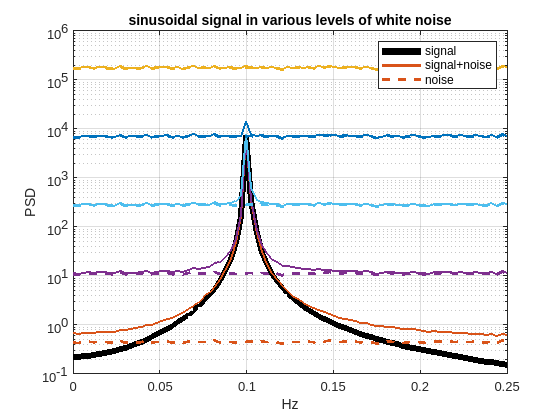


%% Simulation parameters
n = 4096;
t = ((1:n)-1).*0.081; % simulate fMRI timeseries with TR=0.081s
f = 0:((1/0.081)/(n-1)):(1/0.081)/2;

%% Sinusoidal signal
sigFreq = 0.1;
sigAmp = 10;
sigTs = sigAmp.*sin(2*pi*sigFreq*t)';

%% White noise
noiseVar = 3500; % roughly matching fMRI timeseries
alpha = 0; % 0 for white noise, 0.4 for colored noise that roughly matches fMRI timeseries
% multiple noise realizations for easier visualization
nIt = 1000;
noiseTs = nan(n,nIt);
for i = 1:nIt
    noiseTs(:,i) = f_alpha_gaussian ( n, noiseVar, alpha );
end

%% Plot various noise level
figure
sigSpec = fft(sigTs,[],1); sigSpec = sigSpec(1:n/2,:);
sigPsd = (1/(1/0.081*n)) * abs(sigSpec).^2; 
noiseFacList = [0 1/5/5 1/5 1 5 5*5];
for i = 1:length(noiseFacList)
    noiseFac = noiseFacList(i);
    noiseSpec = fft(noiseTs.*noiseFac,[],1); noiseSpec = noiseSpec(1:n/2,:);
    noisePsd = (1/(1/0.081*n)) * abs(noiseSpec).^2;
    sigNnoiseSpec = fft(sigTs+noiseTs.*noiseFac,[],1); sigNnoiseSpec = sigNnoiseSpec(1:n/2,:);
    sigNnoisePsd = (1/(1/0.081*n)) * abs(sigNnoiseSpec).^2;
    if noiseFac==0
        plot(f,mean(sigNnoisePsd,2),'k','LineWidth',5);
        hold on
    else
        hPlot(i) = plot(f, mean( sigPsd + noisePsd ,2) ,'LineWidth',2);
        hold on
        plot(f,mean(noisePsd,2),'--','Color',hPlot(i).Color,'LineWidth',2);
    end
end
grid on

%% Adjust plot
ax = gca;
ax.XLim = [0 0.25];
ax.YScale = 'log';
xlabel('Hz'); ylabel('PSD');
legend({'signal' 'signal+noise' 'noise'},'location','northeast')
drawnow
title('sinusoidal signal in various levels of white noise')

## Periodic signal and aperiodic signal combination in time- and frequency-domain

A similar question can be asked about the combination aperiodic signals--signals that do not repeat over time but affect the shape of the power spectra--with periodic signals. This is investigated below using colored noise$\left(\frac{1}{f^{\alpha } }\right)$giving of different shape of the power spectra depending on the exponent $\alpha$.

We observe the same as for white noise, e.i. as the spectral basline around the peak rises, the peak is not lifted up but submerged. For an absolute measure of the strenght of periodic signals--unbiaised by overlapping periodic signals--one should not attempt to remove the spectral baseline.

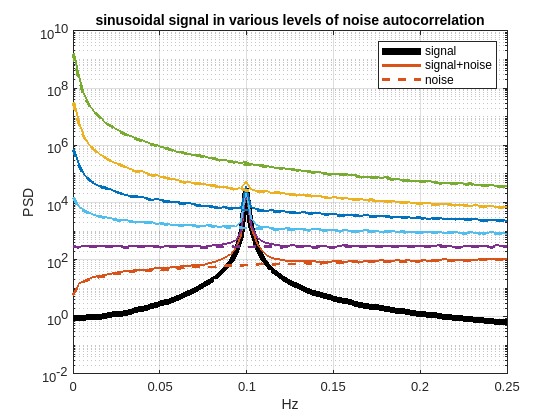

%% Simulation parameters
n = 4096;
t = ((1:n)-1).*0.081; % simulate fMRI timeseries with TR=0.081s
f = 0:((1/0.081)/(n-1)):(1/0.081)/2;

%% Sinusoidal signal
sigFreq = 0.1;
sigAmp = 20;
sigTs = sigAmp.*sin(2*pi*sigFreq*t)';

%% Colored noise
noiseVar = 3500; % roughly matching fMRI timeseries
alphaList = [-0.5 0 0.5 1 1.5 2]; % 0 for white noise, 0.4 for colored noise that roughly matches fMRI timeseries
% multiple noise realizations for easier visualization
nIt = 1000;
noiseTs = nan(n,nIt,length(alphaList));
for ii = 1:length(alphaList)
    for i = 1:nIt
        noiseTs(:,i,ii) = f_alpha_gaussian ( n, noiseVar, alphaList(ii) );
    end
end

%% Plot various noise level
figure
sigSpec = abs(fft(sigTs,[],1)); sigSpec = sigSpec(1:n/2,:);
sigPsd = (1/(1/0.081*n)) * abs(sigSpec).^2; 

plot(f,mean(sigPsd,2),'k','LineWidth',5);
hold on
for ii = 1:length(alphaList)
    noiseSpec = abs(fft(noiseTs(:,:,ii),[],1)); noiseSpec = noiseSpec(1:n/2,:);
    noisePsd = (1/(1/0.081*n)) * abs(noiseSpec).^2; 
    sigNnoiseSpec = abs(fft(sigTs+noiseTs(:,:,ii),[],1)); sigNnoiseSpec = sigNnoiseSpec(1:n/2,:);
    sigNnoisePsd = (1/(1/0.081*n)) * abs(sigNnoiseSpec).^2; 
    hPlot(i) = plot(f,mean(sigNnoisePsd,2),'LineWidth',2);
    plot(f,mean(noisePsd,2),'--','Color',hPlot(i).Color,'LineWidth',2);
end
grid on

%% Adjust plot
ax = gca;
ax.XLim = [0 0.25];
ax.YScale = 'log';
xlabel('Hz'); ylabel('PSD');
legend({'signal' 'signal+noise' 'noise'},'location','northeast')
title('sinusoidal signal in various levels of noise autocorrelation')